classOrder =     -1
     1


label =     -1
    -1
    -1
    -1
    -1
     1
     1
     1
    -1
    -1


score =     0.0877   -0.0877
    1.1120   -1.1120
    1.2593   -1.2593
    0.9112   -0.9112
    0.3780   -0.3780
   -0.0516    0.0516
   -0.6932    0.6932
   -0.2358    0.2358
    0.7274   -0.7274
    0.5428   -0.5428


classLoss = 0.4333

ans = 150×3 table
    TrueLabels    PredictedLabels    PosClassPosterior
    __________    _______________    _________________

    1             -1                 -0.087673        
    1             -1                    -1.112        
    1             -1                   -1.2593        
    1             -1                  -0.91121        
    1             -1                  -0.37803        
    1              1                  0.051637        
    1              1                   0.69324        
    1              1                   0.23581        
    1             -1                  -0.72737        
    1             -1                  -0.54275        
    1             -1                   -1.0961        
    1             -1                  -0.56594        
    1              1                   0.69328        
    1             -1                   -0.8994        

|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstrain-|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    | t            |              | on           | der          |              |
|==================================================================================================================================================|
|    1 | Best   |     0.35526 |      7.4954 |     0.35526 |     0.35526 |       633.17 |            - |       linear |            - |         true |
|    2 | Accept |     0.45395 |       9.477 |     0.35526 |     0.38465 |       587.26 |            - |   polynomial |            3 |        false |
|    3 | Accept |     0.36842 |    0.053972 |     0.35526 |     0.36268 |     0.031866 |            - |   

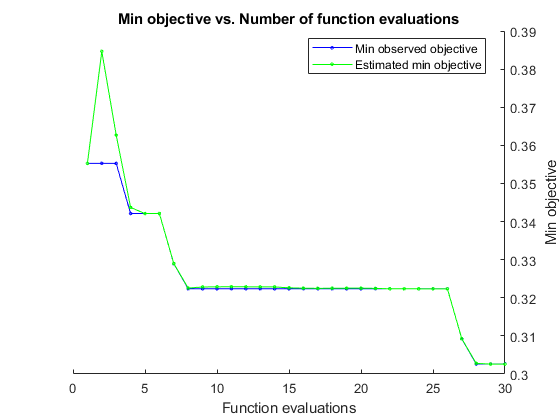

classOrder = 2×1 single column vector
    -1
     1


ans = 152×3 table
    TrueLabels    PredictedLabels     Score  
    __________    _______________    ________

    -1             1                  0.61454
    -1             1                  0.69914
     1            -1                 -0.19341
     1             1                  0.35423
     1            -1                 -0.53113
     1             1                  0.39059
     1            -1                 -0.95031
     1            -1                  -1.0043
     1             1                  0.37557
     1             1                   0.9579
     1             1                  0.36323
     1             1                  0.25305
     1             1                  0.44039
     1            -1                 -0.73103
     1            -1                  -1.6182
     1            -1                 -0.78816


%X = train_feat_vectors';

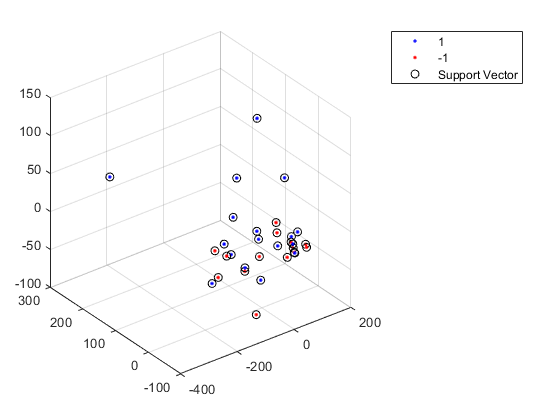

idx1 = train_class_labels==1;
idxm1 = train_class_labels==-1;
idx1 = idx1(1:5:length(idx1));
idxm1 = idxm1(1:5:length(idxm1));
figure
%gscatter(X(:,1),X(:,2),train_class_labels')
scatter3(best(idx1,1)',best(idx1,2)',...
    best(idx1,3)','b.')
hold on;scatter3(best(idxm1,1)',best(idxm1,2)',...
    best(idxm1,3)','r.')
hold on
scatter3(sv(idx1,1),sv(idx1,2),sv(idx1,3),'ko')
hold on;
scatter3(sv(idxm1,1),sv(idxm1,2),sv(idxm1,3),'ko')
%plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)
legend('1','-1','Support Vector')
hold off

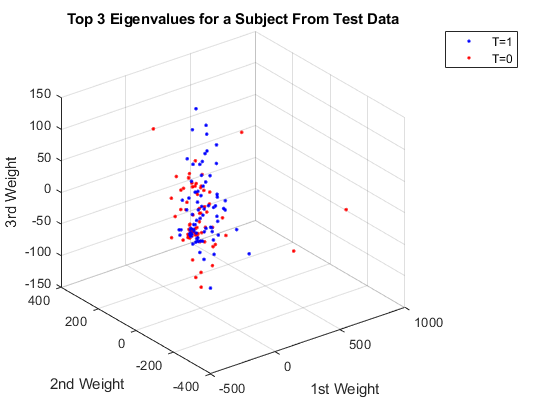

figure;scatter3(test_feat_vectors(1,test_class_labels==1)',test_feat_vectors(2,test_class_labels==1)',test_feat_vectors(3,test_class_labels==1)','b.')
hold on;scatter3(test_feat_vectors(1,test_class_labels==-1)',test_feat_vectors(2,test_class_labels==-1)',test_feat_vectors(3,test_class_labels==-1)','r.')
xlabel('1st Weight')
ylabel('2nd Weight')
zlabel('3rd Weight')
title('Top 3 Eigenvalues for a Subject From Test Data')
legend('T=1','T=0') 

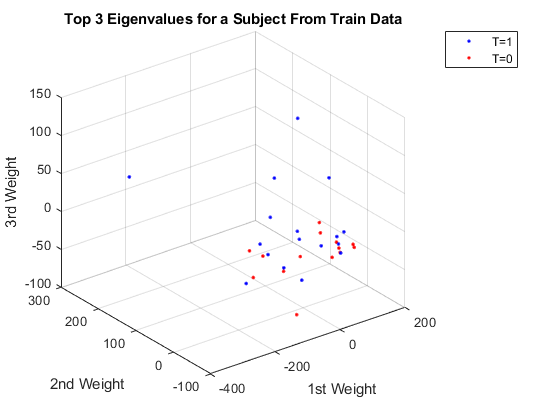

idx1 = train_class_labels==1;
idxm1 = train_class_labels==-1;
idx1 = idx1(1:5:length(idx1));
idxm1 = idxm1(1:5:length(idxm1));

figure;scatter3(train_feat_vectors(1,idx1)',train_feat_vectors(2,idx1)',...
    train_feat_vectors(3,idx1)','b.')
hold on;scatter3(train_feat_vectors(1,idxm1)',train_feat_vectors(2,idxm1)',...
    train_feat_vectors(3,idxm1)','r.')
xlabel('1st Weight')
ylabel('2nd Weight')
zlabel('3rd Weight')
title('Top 3 Eigenvalues for a Subject From Train Data')
legend('T=1','T=0') 